# Particle Discovery Lab

### SETUP

Download the MATLAB workspace for this exercise. Go to the Home menu, Environment section and select "Set Path" -- choose the location of your workspace file. Then run:

load('DoubleMuParked_100k.mat')

## DAY 1 = RECONSTRUCTION

Use energy and momentum conservation to reconstruct a decay of particle X -> mu + mu

% Choose how many events to process
Ntoprocess = input('How many events to process? ');

% Initialize a vector that will hold 1 invariant mass per event
Masses = [];
KineticEnergy = [];

% User-chosen min/max values and resolution
Min = input('Type in your min (in GeV): ');
Max = input('Type in your max (in GeV): ');
n = input('Type in the number of bins: ');
BinWidth = (Max - Min)/n;

% Loop over the number of events with at least 2 muons
disp(['Looping over ' num2str(Ntoprocess) ' events...']);

Looping over 100000 events...


for i = 1:Ntoprocess

    % COMPUTE the mass of particle X -> mu mu
    % SOLUTION: E = E1 + E2, p = p1 + p2 vector sum
    %           mc2 = sqrt( E^2 - p^2 )
    Esum = E(i,1) + E(i,2);
    Px = px(i,1) + px(i,2);
    Py = py(i,1) + py(i,2);
    Pz = pz(i,1) + pz(i,2);
    M = sqrt( Esum^2 - Px^2 - Py^2 - Pz^2 );

    % THINK: Is this mass in your window from Min to Max? 
    %        What should you do if it's outside the window?
    % SOLUTION: discard those events

    if(M > Min && M < Max)
        
        % Calculate the Kinetic Energy of particle X. 
        % Store KE and mass values to plot later  
        % Tip: make sure you mass value if "real" by using real(massvalue)
        Masses = [Masses real(M)];  
        KineticEnergy = [KineticEnergy Esum - real(M)]; 
        % they'll try to solve for v! Redirect to Etotal - Erest = K
    end

end

## HISTOGRAMMING -- create mass and KE histograms

THINK: What do you expect your kinetic energy histogram to look like? What do you expect your mass histogram to look like? 

*SOLUTION: higher energies are always less probable, so falling from 0. Mass is similar: falling from low -> high, but with a bump*

Vocab: imagine plot with 3 bins on x-axis: 0-10, 10-20, 20-30 

"Bin edges": 0, 10, 20, 30 

"Bin low edges": 0, 10, 20

"Bin centers": 5, 15, 25 (want dots on plot to be here!) 

"Bin width": 10

MassEdges = Min:BinWidth:Max;  
MassCenters = MassEdges(1:length(MassEdges)-1) + 0.5*BinWidth; 
KEedges = 0:10:800; %chosen kind of arbitrarily, should fall from 0
KEcenters = KEedges(1:length(KEedges)-1) + 0.5*10; 


Draw a `histogram` of counts versus mass. The `histogram` function needs: Mass values list, Mass "bin edges" list 

figure(1)
histogram(real(Masses),MassEdges,'DisplayStyle','stairs');
xlabel('Mass [GeV]');
ylabel('Number of muon pairs');
hold on; % this lets you draw on top of this plot later
axis manual; % this keeps the axes fixed to where they are now


THINK: What should the ERROR BARS be for each bin? What should you do if the bin has ZERO entries?

*SOLUTION: Error on N = sqrt(N)*

*           Zero is not exact! Just lack of data. Use error_up = 1 (or dig deeper and talk about Poisson upper bound on 0!).*

*           But error bars shouldn't dip below 0 here, that would be unphysical.*

Tools: 

- `histcounts`: gives counts, needs bin edges + input values (mass)

- `errorbar`: draws dots+bars, needs bin centers, y values, down uncert list, up uncert list 

counts = histcounts(Masses, MassEdges);
disp(['Peak bin content: ' num2str(max(counts))]); % just to check

Peak bin content: 4395


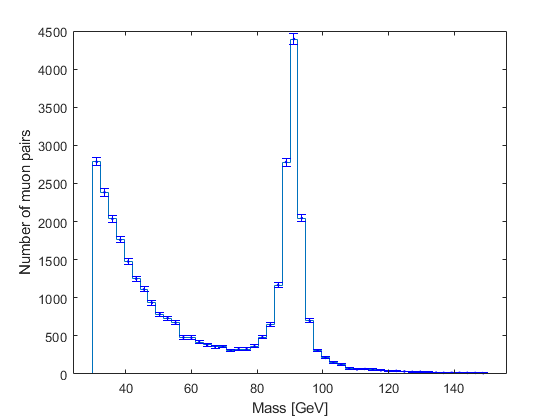


error_up = max(sqrt(counts),1); % avoid error of 0 going up
error_down = sqrt(counts);      % but error going down can be 0
errorbar(MassCenters,counts,error_down,error_up,'b.'); % b. = blue dots
hold off;

Draw another `histogram` of counts vs kinetic energy. Add error bars.

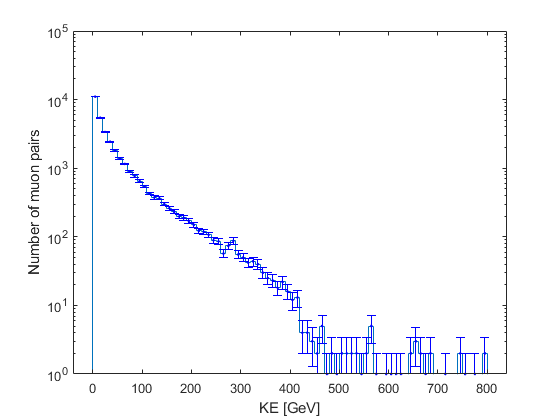

figure(2)
histogram(KineticEnergy,KEedges,'DisplayStyle','stairs'); 
set(gca,'YScale','log'); %log scale on the y axis
xlabel('KE [GeV]'); 
ylabel('Number of muon pairs');
hold on; % this lets you draw on top of this plot later
axis manual; % this keeps the axes fixed to where they are now

KEcounts = histcounts(KineticEnergy, KEedges);
KEerror_up = max(sqrt(KEcounts),1); % avoid error of 0 going up
KEerror_down = sqrt(KEcounts);      % but error going down can be 0
errorbar(KEcenters,KEcounts,KEerror_down,KEerror_up,'b.'); % b. = blue dots
%set(gca,'YScale','linear'); %log scale on the y axis
%ylim([0,10]) % to see if errors up from count of 0 are correct
hold off;

## Great work! 

- **SAVE** these plots to represent your raw data in your report.

- **SAVE** a DAY1 workspace to start from next time (Click in the workspace area, then CTRL-S)

## DAY 2 = FITTING -- fit background on either side of the peak

LOAD your DAY1 workspace

Vocab: imagine a mass plot with a bump in the middle

- "Peak window": region along x-axis under the peak

- "background": smoothly falling slope of random events, including some of the events in the peak window

- "signal": events in the peak window minus the background

CHOOSE mass values or bin numbers for where the peak lies. 

peakmin = input('Type in your peak min boundary (in GeV): ');
peakmax = input('Type in your peak max boundary (in GeV): ');
iMin = round((peakmin-Min)/BinWidth,0)

iMin = 17

iMax = round((peakmax-Min)/BinWidth,0) + 1

iMax = 34

REMOVE the peak window completely from your list of: mass bin edges, mass bin centers, mass counts, mass uncertainties. This forms your BACKGROUND dataset

bkgedges = [MassEdges(1:iMin) MassEdges(iMax:length(MassEdges))];
bkgcounts = [counts(1:iMin) counts(iMax:length(counts))];
bkgcenters = [MassCenters(1:iMin) MassCenters(iMax:length(MassCenters))];
bkgerror_up = [error_up(1:iMin) error_up(iMax:length(error_up))];
bkgerror_down = [error_down(1:iMin) error_down(iMax:length(error_down))];

PERFORM a polynominal fit to the background

    THINK: Which type of curve do you expect will match your data best? Imagine a curve connecting the two sides under your peak.

*    SOLUTION: Probably a line, or 2rd/3rd order poly, likely not much higher*

    Tool: `pollsf` gives fit params, uncerts, y-values, chi^2 value. Needs bin centers, counts, uncertainties, N params

numpars = input('How many params in your polynominal? 1 (flat), 2 (line), etc: ');
[params,paramerrs,fityvals,chisq] = pollsf(bkgcenters,bkgcounts,bkgerror_up,numpars);

EVALUATE your fit by chi^2 and plotting

- Plotting: does the shape make any sense? 

- Chi^2 is defined in Eq. 29. It describes the difference between the points and the fitted curve. LARGER chi^2 tends to mean more difference or scatter of points.

- OPTIMALLY, Chi^2 / (# points - # parameters) is around 1

REPEAT fitting until you are satisfied with both of these metrics

disp(['Chi2/dof = ' num2str(chisq/(length(bkgcenters)-numpars))])

Chi2/dof = 1.3448


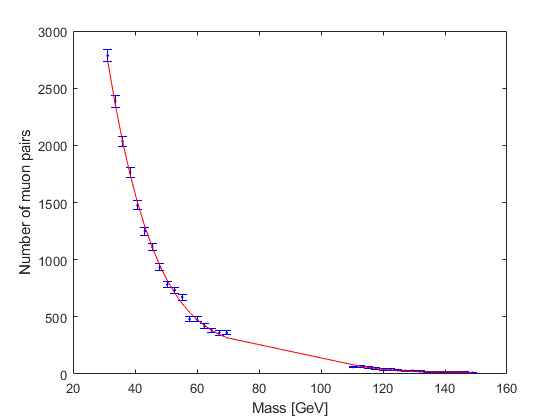

params = fliplr(params');
fittedbkgcounts = polyval(params,bkgcenters);

figure(3)
errorbar(bkgcenters,bkgcounts,bkgerror_down,bkgerror_up,'b.');
xlabel('Mass [GeV]');
ylabel('Number of muon pairs');
hold on;
plot(bkgcenters,fittedbkgcounts,'r-')
hold off;

## SUBTRACTION -- now you will subtract that background from data

THINK: How will you estimate background in the signal peak window?

What do you expect the curve to look like after background subtraction?

*SOLUTION: evaluate the function at x-values inside the peak window After subtraction should look like a ~Gaussian peak*

fittedcounts = polyval(params,MassCenters); % more x-axis bins than before

PLOT the background curve on top of your mass histogram (save it!)

THINK: Are your estimated bkg values at all uncertain?

*SOLUTION: Yes, of course! But we have not discussed covariance and will make the ~safe assumption that our background uncert is small. The pollsf function chooses to return only variances, but you could edit it to return the whole matrix!*

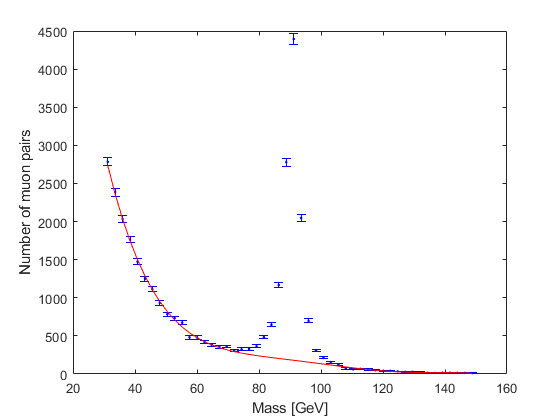

figure(4)
errorbar(MassCenters,counts,error_down,error_up,'b.');
xlabel('Mass [GeV]');
ylabel('Number of muon pairs');
hold on;
plot(MassCenters,fittedcounts,'r-')
hold off;

EVALUATE signal = data - background

THINK: What should you do if the background estimate is > data? How could you find the uncertainty in data - background?

*SOLUTION: Values < 0 can happen when subtracting background, it's no longer necessarily unphysical. Uncertainty is like radioactivity: err = sqrt(errData^2 + errBkg^2), NOT sqrt after subtracting! You could estimate errBkg = 0, or assume Poisson and say errBkg = sqrt(N)*

sigcount = counts-fittedcounts;
sigerror_up = max(sqrt(counts+fittedcounts),1); % again, up error not 0
sigerror_down = sqrt(counts+fittedcounts);

PLOT the signal-only peak with ERROR BARS

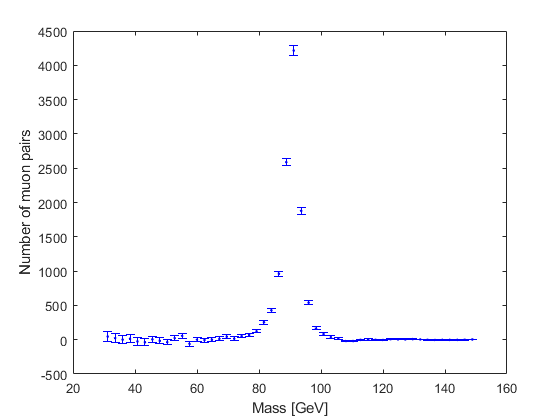

figure(3)
errorbar(MassCenters,sigcount,sigerror_up,sigerror_down,'b.'); 
xlabel('Mass [GeV]');
ylabel('Number of muon pairs');

## Great work! 

- **SAVE** the data+background and signal-only plots as analysis in your report.

- **SAVE** a DAY2 workspace!

## DAY 3 = CHARACTERIZATION of your signal

LOAD your DAY2 workspace

EXTRACT the characteristics of your signal peak

THINK: Which statistical distribution describes your signal peak?

**CURVE FITTING app: Open this from the "Apps" menu**. Select variables containing your x and y data and the function you'd like. Find the MEAN and WIDTH with uncertainties in the output.

*SOLUTION: they should do well with a Gaussian shape, and can add more orders to the Gaussian for fitting multiple Upsilon meson curves. They can do this without typing anything here, but ****I've saved the fit to the workspace**** (Fit -> SaveToWorkspace) to print some values. *

gausparams = coeffvalues(signalGaus)           % signalGaus is the name of the fit I saved

gausparams = 	1.0e+03 *

    4.0387    0.0908    0.0034


intervals = confint(signalGaus)                % uncertainties given as intervals above/below

intervals = 	1.0e+03 *

    3.8535    0.0907    0.0032
    4.2240    0.0910    0.0036



mu = gausparams(2);                             % b is the mean directly
mu_uncert = intervals(2,2) - mu;                
sigma = gausparams(3)/sqrt(2);                  % c is the whole demoninator = sqrt(2)*sigma
sigma_uncert = intervals(2,3)/sqrt(2) - sigma;  % uncert_sigma = uncert_c/sqrt(2)

disp(['Gaussian mean = ' num2str(mu) ' +/- ' num2str(mu_uncert)]);

Gaussian mean = 90.8264 +/- 0.12807


disp(['Gaussian width = ' num2str(sigma) ' +/- ' num2str(sigma_uncert)]);

Gaussian width = 2.4124 +/- 0.12747


COMPARE NSignal in signal peak to NBackground under the peak region

THINK: how can you find the number of events in the signal peak? How can you find the number of bkg events under the peak?

PRINT these values along with their uncertainties

*SOLUTION: NSignal = sum up counts from "sig counts". NBackground = sum up counts from "fittedcounts". Of course, the students are free to integrate their 2 fitted functions from peakmin to peakmax, but this is difficult to program. For uncertainties, they should be able to prove that sqrt(SummedTotalN) is really what you get from propagation of sqrt(N) errors through the sum.*

bkginpeak = fittedcounts(iMin:iMax-1);
peakcounts = counts(iMin:iMax-1);
siginpeak = sigcount(iMin:iMax-1);

disp(['Number of background events in peak = ' num2str(sum(bkginpeak))...
     ' +/- ' num2str(sqrt(sum(bkginpeak)))]);

Number of background events in peak = 3312.7702 +/- 57.5567


disp(['Number of signal events in peak = ' num2str(sum(siginpeak))...
     ' +/- ' num2str(sqrt(sum(peakcounts+bkginpeak)))]);

Number of signal events in peak = 11455.2298 +/- 134.4648


### Almost done!

THINK:

- Can you statistically distinguish signal from background?

- Can you find this particle with a web search for you mass?

- Research this particle (pdg.gov), find its width (capital Gamma)

- Do your mass & width agree with the known values within their uncertainties? Find percent differences and also discrepancy/significance.

- If your width is *much* larger than accepted, why might this be?

*SOLUTION: Generally their masses should agree within the observed widths, and usually within a few times the parameter uncertainty. For Z bosons (short-lived) the width should also agree because it is large (several GeV). For the mesons their width will be MUCH too large -- the CMS detector resolution is not fine enough to measure the lifetime of these particles and the width is inflated. *